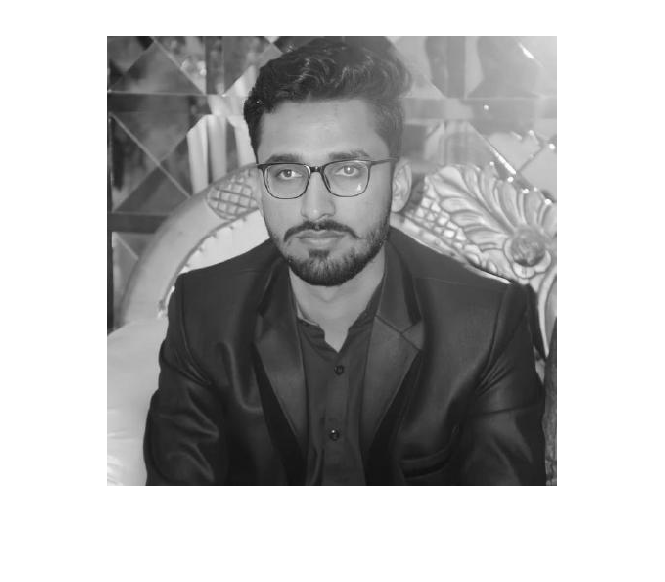

A = rgb2gray(imread("E:/Matlab/assets/sami.jpeg"));
figure;imshow(A);

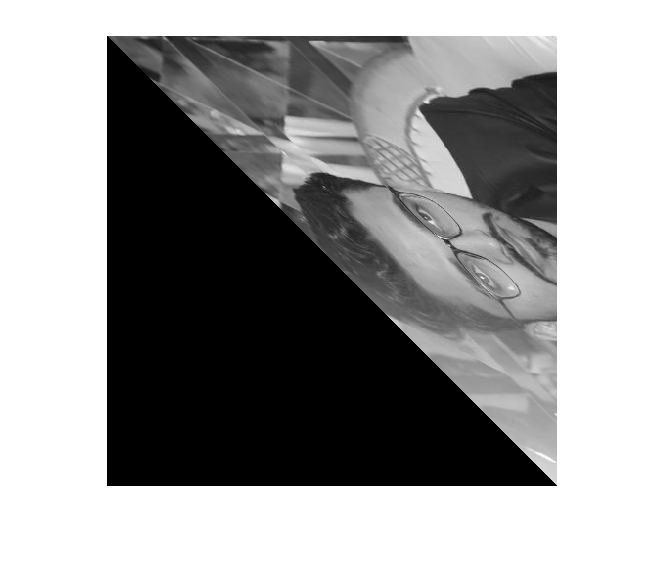


[R,C] = size(A);

% Translation matrix
T = [0 1 0;1 1 0;0 0 1];

B = zeros(R, C);

for i = 1:R
    for j = 1:C
        % Apply the transformation
        transformed_coordinates = T * [i; j; 1];
        
        % Extract the transformed X and Y coordinates
        X = transformed_coordinates(1);
        Y = transformed_coordinates(2);
        % Check if the transformed coordinates are within the bounds of the original image
        if X >= 1 && X <= R && Y >= 1 && Y <= C
            B(X,Y) = A(i,j);
        end
        
    end
end

figure;imshow(B,[]);